# PROYECTO PRIME

Teresa González García y María José Medina Hernández

format compact; clear all; close all;

## 1. Elección de los parámetros de simulación

### Parámetros generales

Fs=250*10^3; % Frecuencia de muestreo
Ts=1/Fs; % Periodo de muestreo

### Parámetros de modulación PSK

m_ary=[2 4 8]; % Número de símbolos de la constelación PSK
m_dpsk=log2(m_ary);

### Parámetros de modulación OFDM

Nc= 96; % Número de portadoras
NFFT=512; % Tamaño FFT
Ncp=48; % Tamaño prefijo ciclico
Tsimb=2.24*10^-3; % NFFT*Ts + Ncp*Ts. Duracion total simbolo OFDM
delta_f=Fs/NFFT; % Separacion entre f portadoras

### Parámetros de corrección de errores

R=1/2; %Convolutional coding rate

### Parámetros de aleatorización y desfase

% Secuencia PRBS
scrambler = [0,0,0,0,1,1,1,0,1,1,1,1,0,0,1,0,1,1,0,0,1,0,0,1,0,0,0,0,0,0,1,0,0,0,1,0,0,1,1,0,0,0,1,0,1,1,1,0,1,0,1,1,0,1,1,0,0,0,0,0,1,1,0,0,1,1,0,1,0,1,0,0,1,1,1,0,0,1,1,1,1,0,1,1,0,1,0,0,0,0,1,0,1,0,1,0,1,1,1,1,1,0,1,0,0,1,0,1,0,0,0,1,1,0,1,1,1,0,0,0,1,1,1,1,1,1,1];

### Parámetros de simulación

Para calcular el número de símbolos OFDM por trama, tenemos en cuenta que, como máximo, esta puede durar 100ms ya que es el tiempo máximo en el que se puede considerar el canal estable cuando sea dispersivo. Obtenemos Nofdm = 44.

Tmax=100*10^-3; % Duración máxima de una trama
Nofdm= floor(Tmax/(Tsimb)); % Nofdm

Puesto que se quieren obtener valores de BER fiables inferiores incluso a 10^-4, se necesitan transmitir al menos 10^-4 bits si se quiere obtener esta sensibilidad. Para sensillez del código, se utilizará un número de bits proporcional al número de portadoras, a log2(m-ary) y al número de símbolos OFDM por trama. El mínimo común múltiplo de estos cuatro parámetros es mayor a 10^-4, por lo que es un tamaño válido. En total obtenemos 25344.

Nbits = Nc*lcm(2,3)*Nofdm;

Para calcular el número total de tramas, se divide el número total de bits entre los bits por trama. En total obtenemos 6 para DBPSK, 3 para DQPSK y 2 para DBPSK.

Nbits_trama_DPSK= Nofdm*Nc*m_dpsk;
N_tramas_DPSK=Nbits./Nbits_trama_DPSK;


## 2. Transmisión en un canal ideal

### Transmisión sin aleatorización 

% TODO: poner un flag para que aleatorice o no para demostrar que funciona sin y con aleatorización

% Generación de una secuencia de bits aleatoria
txbits = randi(2,1,Nbits)-1;

% Transmisión con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
x_tx_DBPSK= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT);
x_tx_DQPSK= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT);
x_tx_D8PSK= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT);

% Recepción con modulación en OFDM sobre DBPSK, DQPSK y D8PSK
rxbits_DBPSK=receptor(x_tx_DBPSK, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
rxbits_DQPSK=receptor(x_tx_DQPSK, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
rxbits_D8PSK=receptor(x_tx_D8PSK, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);

#### Cálculo del error de transmisión

Cálculo del error de transmisión mediante la comparación de los bits transmitidos con los recibidos

error_dbpsk = sum(abs(txbits-rxbits_DBPSK))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-rxbits_DQPSK))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-rxbits_D8PSK))

error_d8psk = 0

### 3. Transmisión en presencia de ruido AWGN

Comparativa BERs teóricas frente a simuladas

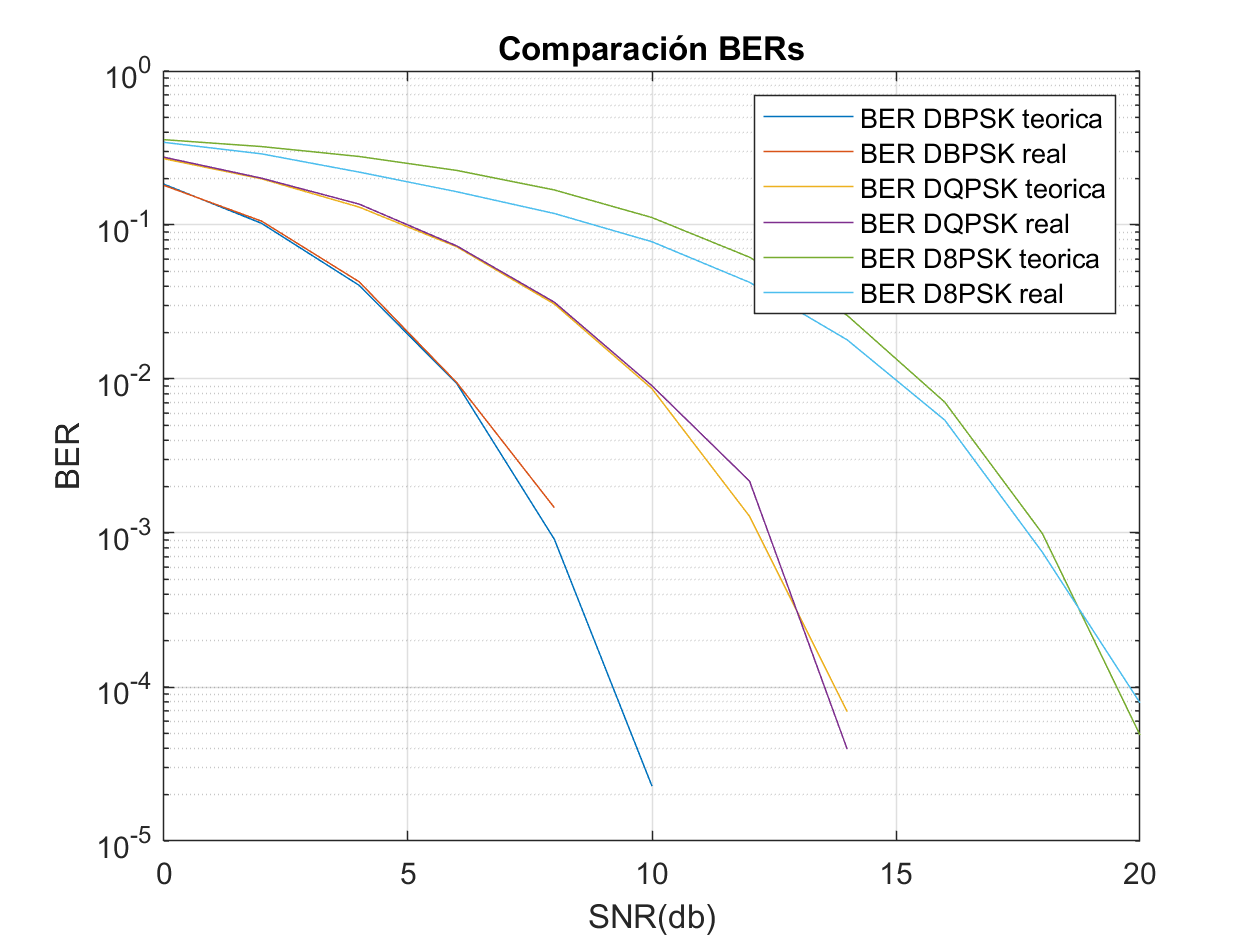

% vector SNR
SNR_db = 0:2:35;

% Cálculo del factor de ancho de banda para distribuir SNR tan solo en la parte
% del espectro con portadoras (Nc)
fb = 10*log10( (NFFT/2)/Nc);

%BER's teoricas de cada modulacion
BER_teor_DBPSK= DBPSK_BER(SNR_db);
BER_teor_DBPSK(find(BER_teor_DBPSK<1e-6))=NaN;
BER_teor_DQPSK= DQPSK_BER(SNR_db);
BER_teor_DQPSK(find(BER_teor_DQPSK<1e-6))=NaN;
BER_teor_D8PSK= D8PSK_BER(SNR_db);
BER_teor_D8PSK(find(BER_teor_D8PSK<1e-6))=NaN;

% Bucle calculo BER_real_DBPSK
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_dbpsk=awgn(x_tx_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_dqpsk=awgn(x_tx_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_d8psk=awgn(x_tx_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_dbpsk=receptor(y_noise_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_dqpsk=receptor(y_noise_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_d8psk=receptor(y_noise_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

% Representacion BER vs SNR para todos los tipos de modulacion
figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

D8PSK + BER CONSTELACION PUNTOS MAS JUNTOS.

        2.   Inclusión de modelo de canal e inclusión de ecualizador

%canal variante en f. Corresponde a un filtro digital de k=9 posiciones en total (en el dominio del tiempo
% discreto):
h=[-0.1,0.3,-0.5,0.7,-0.9,0.7, -0.5, 0.3, -0.1]; % h=[a0...a8]; atenuaciones

   h[n] produce atenuación y retardo por reflexiones dentro de un canal multipath (retardo máximo 8) en la señal a transmitir.

s(t) -> TX

y(t)-> RX

y(t)=conv(s(t),h(t)) -> dominio discreto -> y[n]= conv(s[n],h[n]). 

y[n]=sum(att*s[n-k])- Seguir con esto en latex

H(f) en dbW

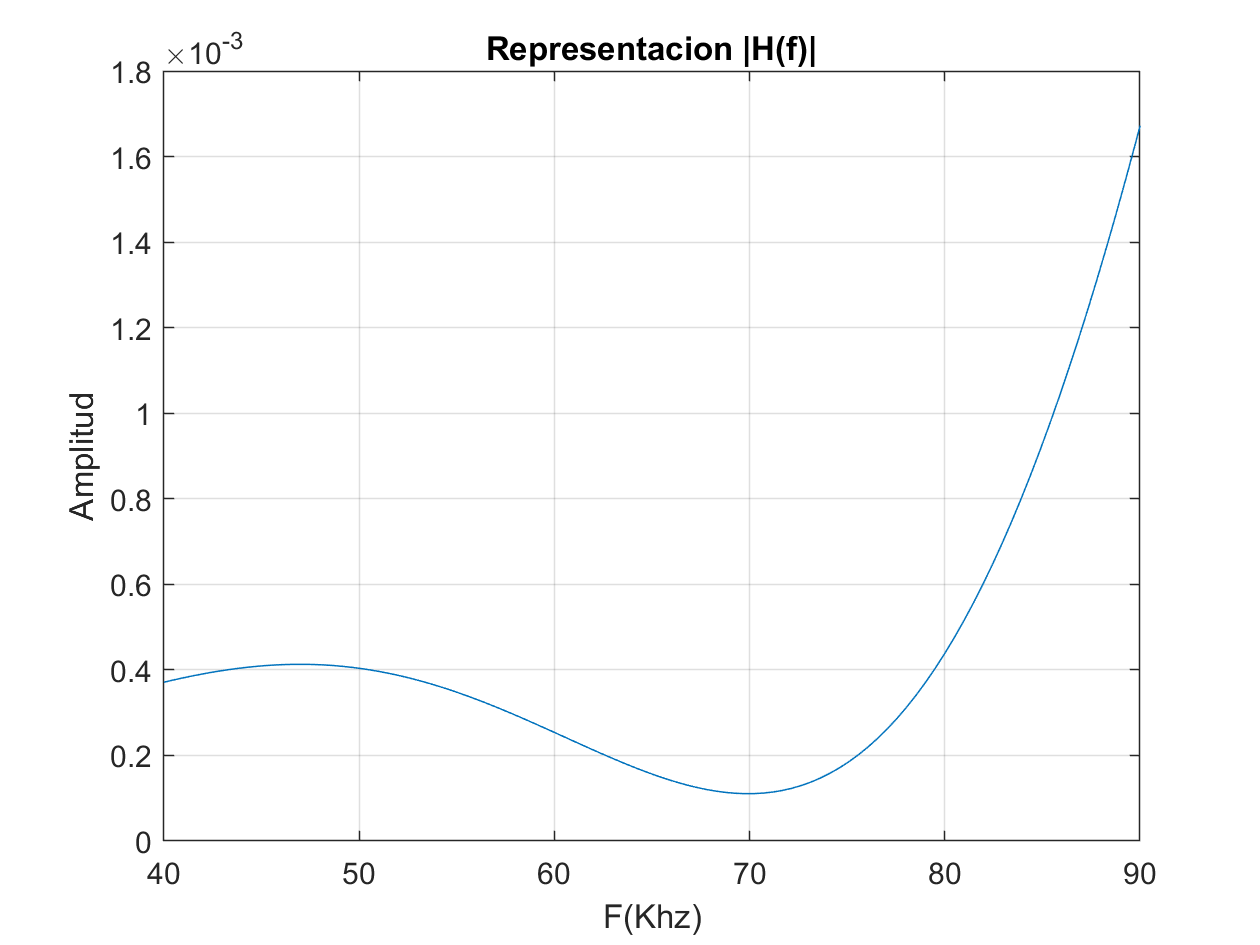

% vector f (paso Fs) -> mitad puntos NFFT espectro + y mitad -. Preguntar

% H(f) es la respuesta al impulso del canal -> FFT.
H=fft(h,NFFT)/NFFT;
f=linspace(-Fs/2,Fs/2, length(H));

%Representacion |H(f)| en el dominio de la frecuencia (unidades naturales)
figure
plot(f/1000,abs(fftshift(H)));
title('Representacion |H(f)|');
xlabel('F(Khz)');
xlim([40,90]);
ylabel('Amplitud');
grid on

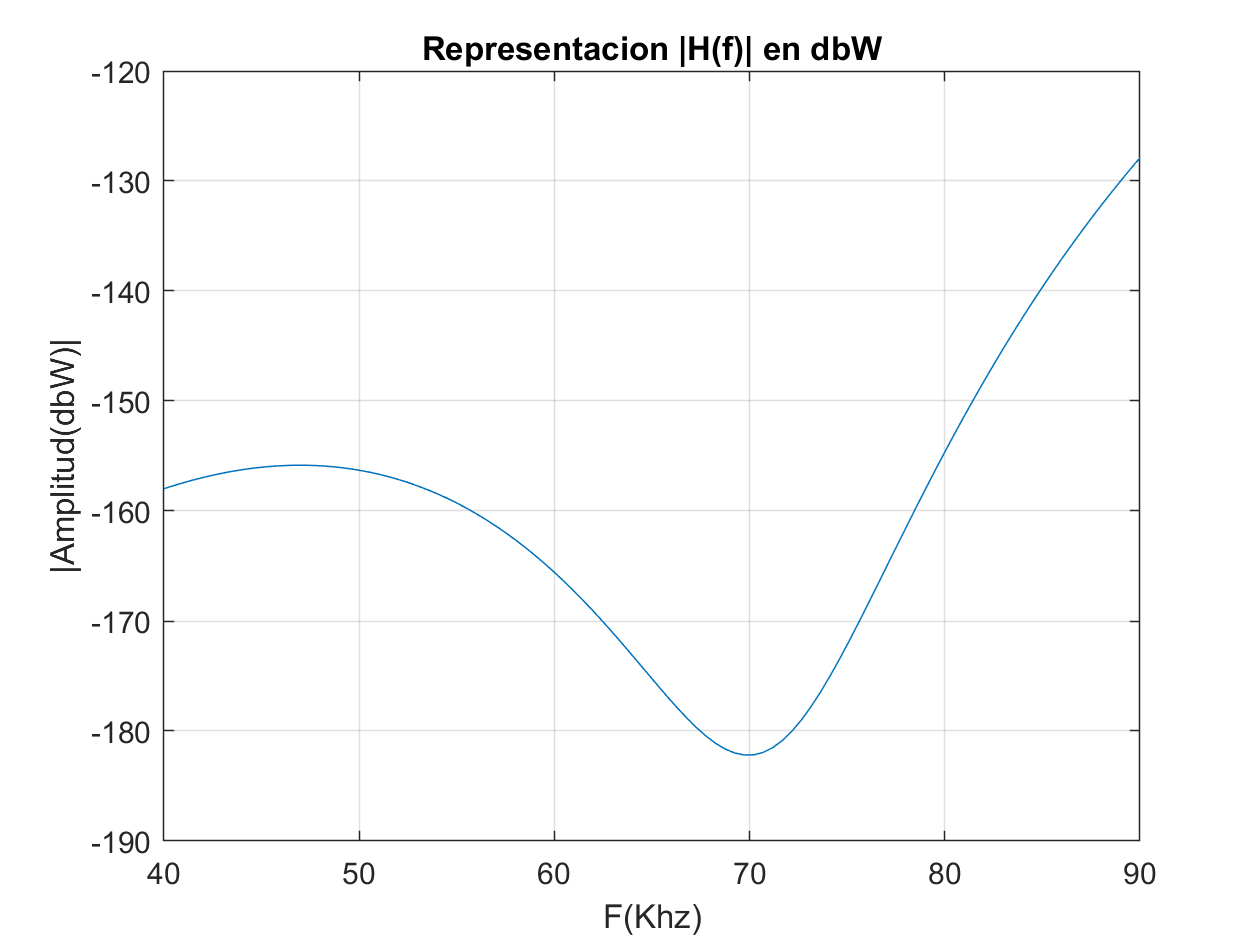

% Representacion |H(f)| el dominio de la frecuencia (db)
figure
plot (f/1000,20*log(abs(fftshift(H))))
title('Representacion |H(f)| en dbW');
xlabel('F(Khz)');
ylabel('|Amplitud(dbW)|');
grid on
xlim([40,90]);

## Con canal

Variables globales

global pilotos_dbpsk
global pilotos_dqpsk
global pilotos_d8psk

%convolucion lineal sin cp y añadimos awgn
y_canal_DBPSK=conv(x_tx_DBPSK,h);
y_canal_DBPSK =y_canal_DBPSK(1:end-length(h)+1)

y_canal_DBPSK =    -0.6000    2.0757   -3.3301    3.2429   -2.6325    1.3923   -0.2116   -1.2711    1.0209    1.1262   -0.3462   -1.4629   -1.4091    2.3702    2.5669   -2.9155   -1.6562    1.4990   -0.6553    2.0906    2.0014   -5.5827   -0.9644    5.9641   -1.1034   -2.6679    1.4741   -1.3906    0.7802    2.5239   -3.6060    0.0049    4.2573   -3.3401   -2.3276    4.0679    0.0077   -1.4411    0.4429   -2.4459    1.1082    4.9782   -2.9404   -4.9990    3.2564    3.0487   -1.4690   -0.6439   -1.5409   -0.6178


y_canal_DQPSK=conv(x_tx_DQPSK,h);
y_canal_DQPSK =y_canal_DQPSK(1:end-length(h)+1)

y_canal_DQPSK =     0.4000   -2.4510    5.4775   -6.0518    3.8563   -1.7397   -1.0523    1.9849    1.3378   -3.9696    1.6733    3.6218   -5.8417    0.5176    5.8460   -4.6043   -0.2648    3.3055   -5.2733    2.6791    4.5592   -6.1401    0.8213    2.3319   -3.1697    4.2057   -0.8753   -5.2444    5.4688    0.1368   -3.7700    3.0548   -1.9251    1.0033    3.0364   -6.7390    2.6536    5.1096   -6.6792    2.9924    1.3092   -6.6684    8.5561   -0.2521  -10.5133    9.6431    1.2014   -8.8828    8.1920   -2.2436



y_canal_D8PSK=conv(x_tx_D8PSK,h);
y_canal_D8PSK =y_canal_D8PSK(1:end-length(h)+1)

y_canal_D8PSK =     1.1657   -2.0870    1.3675   -3.2316    8.2980   -6.3002    5.9146   -6.4874   -1.2341    7.3949   -3.8601   -1.0687    4.3465   -4.9673    0.1635    3.4893   -2.7565    2.8952   -0.6036   -5.4964    5.1165    1.1712   -3.8729    3.9846   -2.2788   -3.3140    5.5604   -1.7227   -1.5754    4.3082   -5.0011   -1.6973    6.6341   -1.8247   -2.1988    1.5464   -2.6576    1.4753    3.2450   -2.7522   -0.7841    0.8727   -0.8355    1.0892    0.5292   -0.3229   -0.3195   -2.0692    1.4911    3.0504


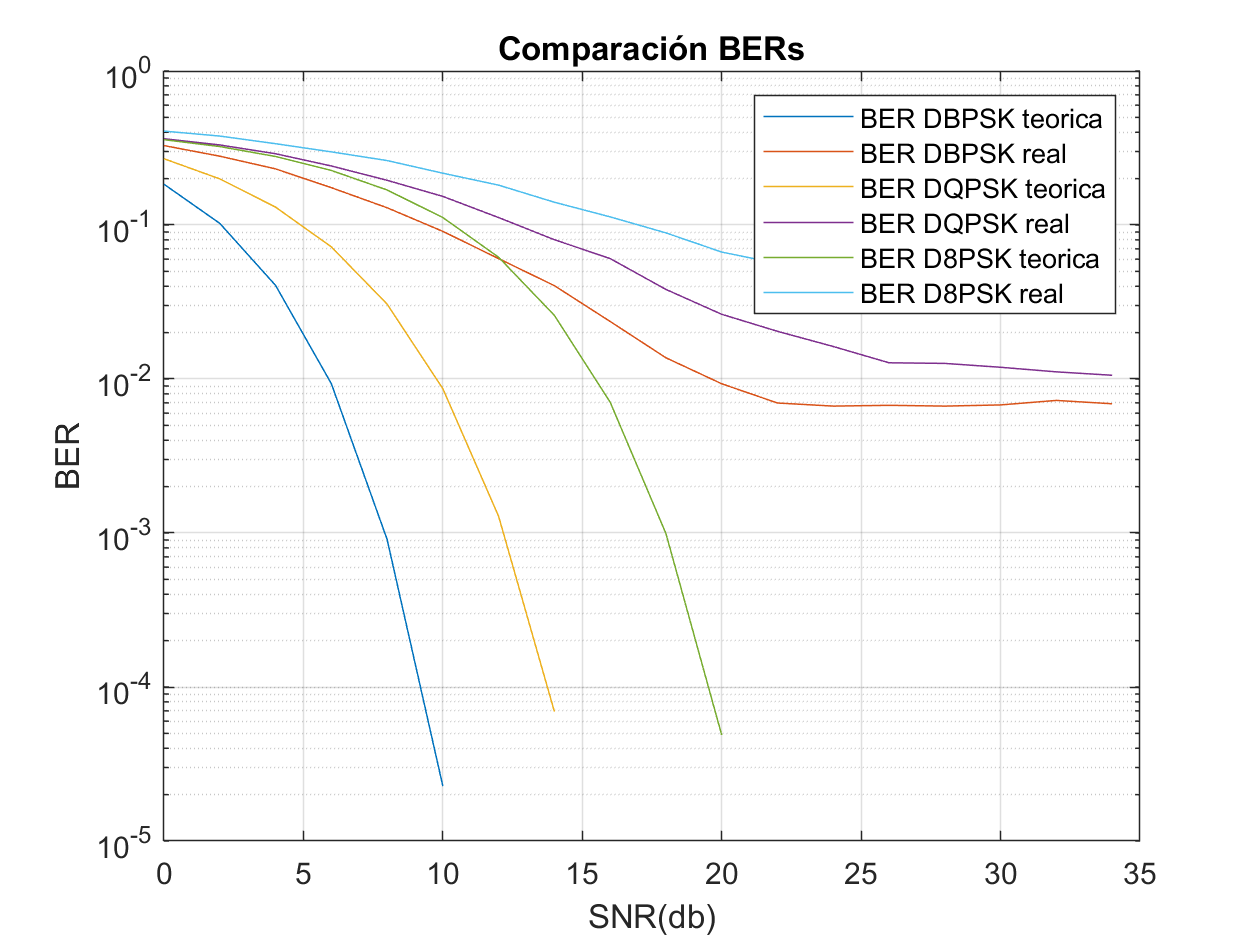

%añadimos el ruido
for k=1:length(SNR_db)
    %y_noise=zeros(1, length(x_tx_DBPSK));
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_dqpsk=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT);
    y_rx_noise_canal_d8psk=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

FONDO DE BER EN TORNO 10^-2. eq lo quitara. BPSK MENOR BER

%incluir prefijo ciclico ncp=48. asi se puede recuperar el canal con la
%inversa (problema FFT)
%vectores extendidos
x_tx_DBPSK_cp= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_DQPSK_cp= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT, Ncp);
x_tx_D8PSK_cp= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT, Ncp);

Suponemos que desconocemos el canal.  Finjimos que conocemos el primer simbolo OFDM que recibes entre el primero que has enviado para estimar el canal

%receptor sin ruido para ver que nos quita bien el prefijo

y_rx_DBPSK_cp=receptor(x_tx_DBPSK_cp, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_DQPSK_cp=receptor(x_tx_DQPSK_cp, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
y_rx_D8PSK_cp=receptor(x_tx_D8PSK_cp, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);


Comprobacion tras ecualizacion y sin ruido error=0.

error_dbpsk = sum(abs(txbits-y_rx_DBPSK_cp))

error_dbpsk = 0

error_dqpsk = sum(abs(txbits-y_rx_DQPSK_cp))

error_dqpsk = 0

error_d8psk = sum(abs(txbits-y_rx_D8PSK_cp))

error_d8psk = 0

Convolucionamos con la extendida

y_canal_DBPSK_cp=conv(x_tx_DBPSK_cp,h);
y_canal_DBPSK_cp =y_canal_DBPSK_cp(1:end-length(h)+1);

y_canal_DQPSK_cp=conv(x_tx_DQPSK_cp,h);
y_canal_DQPSK_cp =y_canal_DQPSK_cp(1:end-length(h)+1);

y_canal_D8PSK_cp=conv(x_tx_D8PSK_cp,h);
y_canal_D8PSK_cp =y_canal_D8PSK_cp(1:end-length(h)+1);

Añadimos ruido para calcular BER

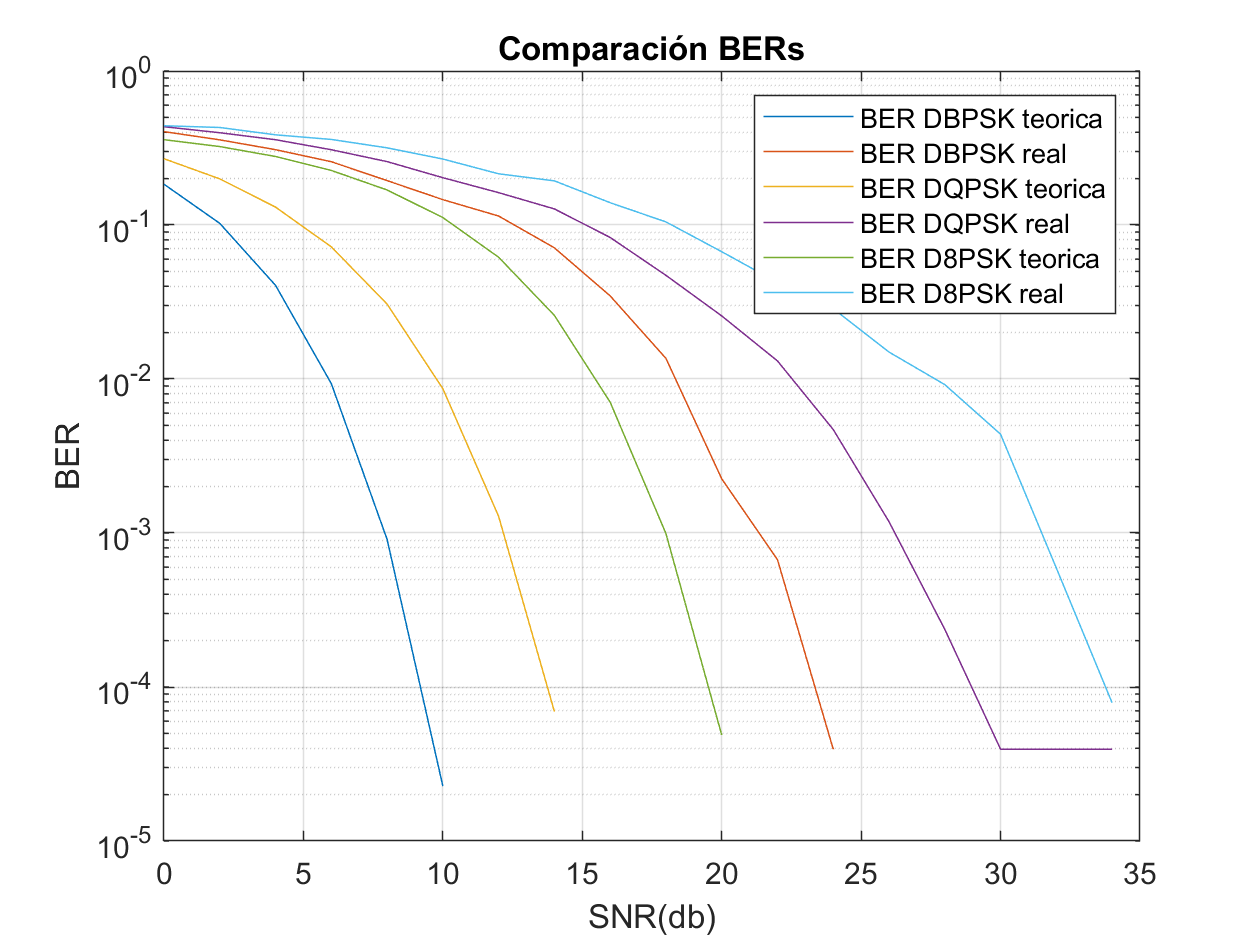

%añadimos el ruido

for k=1:length(SNR_db)
  
    y_noise_canal_dbpsk=awgn(y_canal_DBPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_dqpsk=awgn(y_canal_DQPSK_cp,SNR_db(k)-fb,'measured');
    y_noise_canal_d8psk=awgn(y_canal_D8PSK_cp,SNR_db(k)-fb,'measured');
    
    y_rx_noise_canal_dbpsk_cp=receptor(y_noise_canal_dbpsk, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_dqpsk_cp=receptor(y_noise_canal_dqpsk, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp);
    y_rx_noise_canal_d8psk_cp=receptor(y_noise_canal_d8psk, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp);
    
    
    diferencia_dbpsk=abs(txbits-y_rx_noise_canal_dbpsk_cp);
    diferencia_dqpsk=abs(txbits-y_rx_noise_canal_dqpsk_cp);
    diferencia_d8psk=abs(txbits-y_rx_noise_canal_d8psk_cp);
    
    BER_real_DBPSK(k)= (sum(diferencia_dbpsk)/length(txbits));
    BER_real_DBPSK(find(BER_real_DBPSK<1e-6))=NaN;
    
    BER_real_DQPSK(k)= (sum(diferencia_dqpsk)/length(txbits));
    BER_real_DQPSK(find(BER_real_DQPSK<1e-6))=NaN;
    
    BER_real_D8PSK(k)= (sum(diferencia_d8psk)/length(txbits));
    BER_real_D8PSK(find(BER_real_D8PSK<1e-6))=NaN;
end

figure
semilogy(SNR_db,BER_teor_DBPSK)
hold on;
semilogy(SNR_db, BER_real_DBPSK)
hold on;
semilogy(SNR_db,BER_teor_DQPSK)
hold on;
semilogy(SNR_db, BER_real_DQPSK)
hold on;
semilogy(SNR_db,BER_teor_D8PSK)
hold on;
semilogy(SNR_db, BER_real_D8PSK)
hold on;
title('Comparación BERs')
xlabel('SNR(db)')
ylabel('BER')
legend('BER DBPSK teorica', 'BER DBPSK real', 'BER DQPSK teorica', 'BER DQPSK real', 'BER D8PSK teorica', 'BER D8PSK real')
grid on

## FEC

- Parametros

%añadimos nuevos bits por la redundancia del FEC (x2), nuevos (menor) bits por trama y
%numeros de tramas
%se meten menos nbits por trama de info porque hay que añadir 8 bits al
%final.


    2. Interleaving


%txtrama
%funcion interleaving que mete el simbolo y nos devuelve el simbolo interleveada, los dos en vector.
% alloco matrices
%trasponer
%vector reshape

%prefijo añadido
x_tx_DBPSK_cp_ileav= transmisor(txbits', m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_DQPSK_cp_ileav= transmisor(txbits', m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc,scrambler, Nofdm, NFFT, Ncp, R);
x_tx_D8PSK_cp_ileav= transmisor(txbits', m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc,scrambler, Nofdm, NFFT, Ncp, R);


%rxtrama
%deshacer 
%en tx trama crear un bucle para cada simbolo. 44 simbolos por trama. cada
%simbolo interleaving. se devuelve u argumento.
y_rx_DBPSK_cp_ileav=receptor(x_tx_DBPSK_cp_ileav, m_ary(1), Nbits_trama_DPSK(1), N_tramas_DPSK(1), Nc, scrambler, Nofdm, NFFT, Ncp, R);
y_rx_DQPSK_cp_ileav=receptor(x_tx_DQPSK_cp_ileav, m_ary(2), Nbits_trama_DPSK(2), N_tramas_DPSK(2), Nc, scrambler, Nofdm, NFFT, Ncp, R);
y_rx_D8PSK_cp_ileav=receptor(x_tx_D8PSK_cp_ileav, m_ary(3), Nbits_trama_DPSK(3), N_tramas_DPSK(3), Nc, scrambler, Nofdm, NFFT, Ncp, R);


Comprobar error tras interleaving

error_dbpsk = find(txbits-y_rx_DBPSK_cp_ileav)

error_dbpsk =
  1×0 empty double row vector


error_dqpsk = find(txbits-y_rx_DQPSK_cp_ileav)

error_dqpsk =
  1×0 empty double row vector


error_d8psk = find(txbits-y_rx_D8PSK_cp_ileav)

error_d8psk =
  1×0 empty double row vector
